fs = 8000;
f = [0 1200 1500 fs/2] * (2/fs);
H = [1 1 0 0]

H =      1     1     0     0


W = [1 12]

W =      1    12



N=12;
B12 = firpm(N, f, H, W);
[H12, w] = freqz(B12, 1, 512, fs)

H12 =    1.4090 + 0.0000i
   1.4081 - 0.0519i
   1.4054 - 0.1037i
   1.4010 - 0.1554i
   1.3948 - 0.2069i
   1.3868 - 0.2582i
   1.3770 - 0.3092i
   1.3655 - 0.3599i
   1.3522 - 0.4102i
   1.3372 - 0.4600i


w = 1.0e+03 *

         0
    0.0078
    0.0156
    0.0234
    0.0312
    0.0391
    0.0469
    0.0547
    0.0625
    0.0703



N=24;
B24 = firpm(N, f, H, W);
[H24, ~] = freqz(B24, 1, 512, fs)

H24 =    1.2319 + 0.0000i
   1.2284 - 0.0906i
   1.2179 - 0.1807i
   1.2005 - 0.2696i
   1.1764 - 0.3568i
   1.1456 - 0.4419i
   1.1084 - 0.5242i
   1.0650 - 0.6033i
   1.0157 - 0.6787i
   0.9609 - 0.7499i



N=36;
B36 = firpm(N, f, H, W);
[H36, ~] = freqz(B36, 1, 512, fs)

H36 =    1.1014 + 0.0000i
   1.0944 - 0.1214i
   1.0735 - 0.2411i
   1.0390 - 0.3574i
   0.9915 - 0.4689i
   0.9316 - 0.5740i
   0.8602 - 0.6713i
   0.7783 - 0.7595i
   0.6873 - 0.8374i
   0.5882 - 0.9042i


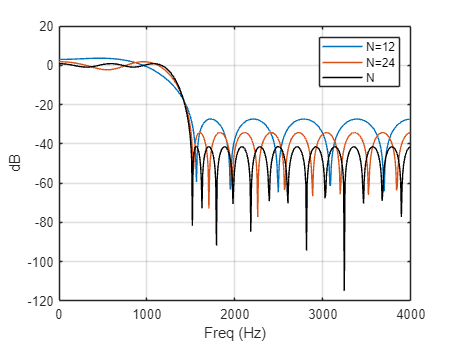


plot(w, 20*log10(abs(H12)), w, 20*log10(abs(H24)), w, 20*log10(abs(H36)), 'k')
grid; xlabel('Freq (Hz)'); ylabel('dB'); legend('N=12', 'N=24', N='36');